# Room Impulse Response Simulation with Stochastic Ray Tracing

Room impulse response simulation aims to model the reverberant properties of a space without having to perform acoustic measurements. Many geometric and wave-based room acoustic simulation methods exist in the literature [1]. 

The image-source method is a popular geometric method (for an example, see [Room Impulse Response Simulation with the Image-Source Method and HRTF Interpolation](docid:audio_ug#mw_8d4c3bb6-38ee-4eca-8df8-bdbef30dfb4d)). One drawback of the image-source method is that it only models specular reflections between a transmitter and a receiver. There are other geometric methods that address this limitation by also taking sound diffusion and diffraction into account. Stochastic ray tracing is one such method.

This example showcases a stochastic ray tracing method for a simple "shoebox" (cuboid) room.

## Stochastic Ray Tracing Overview

Ray tracing assumes that sound energy travels around the room in rays. The rays start at the sound source, and are emitted in all directions, following a uniform random distribution. In this example, you follow (trace) rays as they bounce off obstacles (walls, floor and ceiling) in the room. At each ray reflection, you compute the measured ray energy at the receiver. You use the measured energy to update a frequency-dependent histogram. You then compute the room impulse response by weighting a Poisson random process by the histogram values [2].

## Define Room Parameters

 Simulate the impulse response of the shoebox empty room.

 Define the room dimensions, in meters (width, length, and height, respectively).

roomDimensions = [10.3632 7.3152 3.3528];

Treat the transmitter as a point within the space of the room. Assume that the receiver is a sphere with radius 8.75 cm.

%sourceCoord = [0.8108 0.1 1];
%receiverCoord = [0.8108 0.5 1];
%r = 0.0875;

%sourceCoord = [3.6576 0.1 1];
%receiverCoord = [3.6576 0.5 1];
%r = 0.01;

sourceCoord = [5.4864 0.1 1];
receiverCoord = [5.4864 0.5 1];
r = 0.01;

Plot the room space along with the receiver (red circle) and transmitter (blue x).

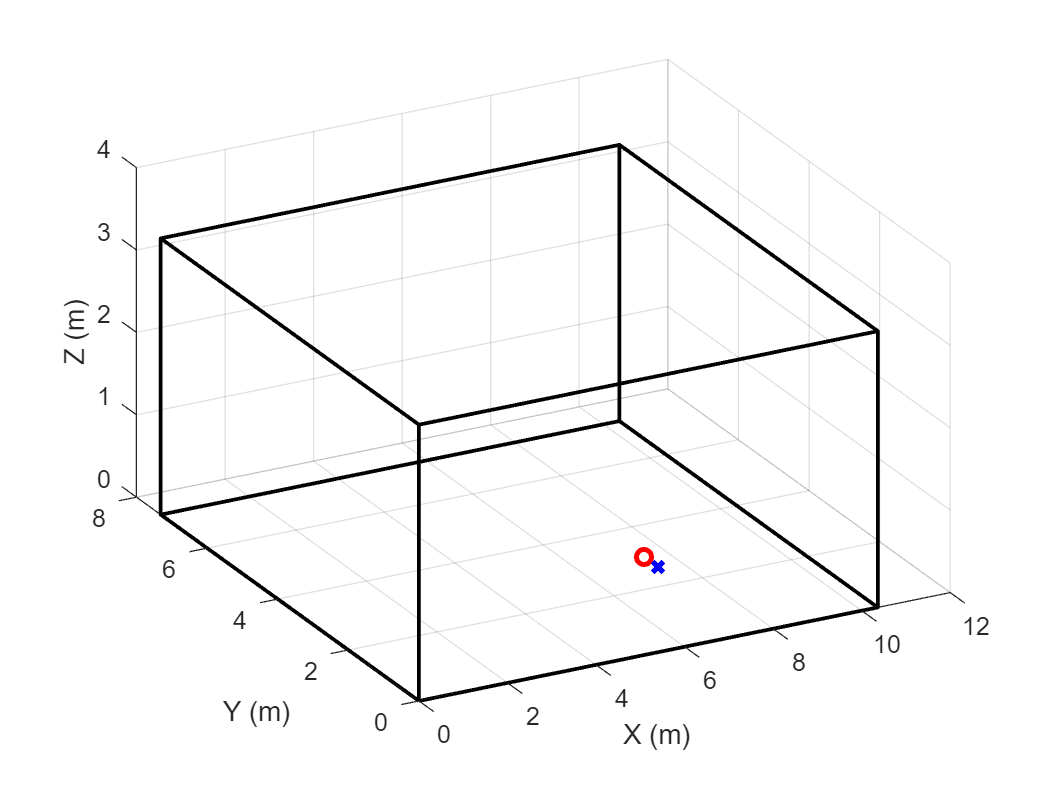

h = figure;
plotRoom(roomDimensions,receiverCoord,sourceCoord,h)

## Generate Random Rays

First, generate rays emanating from the source in random directions.

Set the number of rays.

N = 5000;

Generate the rays using the helper function `RandSampleSphere`. `rays` is a *N-by-3* matrix. Each row of `rays` holds the three-dimensional ray vector direction.

rng(0)
rays = RandSampleSphere(N);
size(rays)

ans =         5000           3


## Define Reflection and Scattering Coefficients

A sound ray is reflected when it hits a surface. The reflection is a combination of a specular component and a diffused component. The relative strength of each component is determined by the reflection and scattering coefficients of the surfaces.

Define the absorption coefficients of the walls. The absorption coefficient is a measure of how much sound is absorbed (rather than reflected) when hitting a surface. 

The frequency-dependent absorption coefficients are defined at the frequencies in the variable `FVect` [4].

FVect = [125 250 500 1000 2000 4000];

A = [0.08 0.09 0.12 0.16 0.22 0.24;
    0.08 0.09 0.12 0.16 0.22 0.24;
    0.08 0.09 0.12 0.16 0.22 0.24;
    0.08 0.09 0.12 0.16 0.22 0.24;
    0.01 0.03 0.05 0.02 0.02 0.02;
    0.09 0.08 0.21 0.26 0.27 0.37].';

Derive the reflection coefficients of the six surfaces from the absorption coefficients. 

R = sqrt(1-A);

Define the frequency-dependent scattering coefficients [5]. The scattering coefficient is defined as one minus the ratio between the specularly reflected acoustic energy and the total reflected acoustic energy. 

D = [0.05 0.3 0.7 0.9 0.92 0.94;
     0.05 0.3 0.7 0.9 0.92 0.94; 
     0.05 0.3 0.7 0.9 0.92 0.94; 
     0.05 0.3 0.7 0.9 0.92 0.94; 
     0.01 0.05 0.1 0.2 0.3 0.5;
     0.01 0.05 0.1 0.2 0.3 0.5];

## Initialize Energy Histogram

As you trace the rays, you update a two-dimensional histogram of the energy detected at the receiver. The histogram records values along time and frequency.

Set the histogram time resolution, in seconds. The time resolution is typically much larger than the inverse of the audio sample rate.

histTimeStep = 0.0010;

Compute the number of histogram time bins. In this example, limit the impulse response length to one second.

impResTime = 3;
nTBins = round(impResTime/histTimeStep);

The ray tracing algorithm is frequency-selective. In this example, focus on six frequency bands, centered around the frequencies in `FVect`.

The number of frequency bins in the histogram is equal to the number of frequency bands.

nFBins = length(FVect);

Initialize the histogram.

TFHist = zeros(nTBins,nFBins);

## Perform Ray Tracing

Compute the received energy histogram by tracing the rays over each frequency band. When a ray hits a surface, record the amount of diffused ray energy seen at the receiver based on the diffused rain model [2]. The new ray direction upon hitting a surface is a combination of a specular reflection and a random reflection.  Continue tracing the ray until its travel time exceeds the impulse response duration. 

for iBand = 1:nFBins
    % Perform ray tracing independently for each frequency band.
    for iRay = 1:size(rays,1)
        % Select ray direction
        ray = rays(iRay,:);
        % All rays start at the source/transmitter
        ray_xyz = sourceCoord;
        % Set initial ray direction. This direction changes as the ray is
        % reflected off surfaces.
        ray_dxyz = ray;
        % Initialize ray travel time. Ray tracing is terminated when the
        % travel time exceeds the impulse response length.
        ray_time = 0;
        % Initialize the ray energy to a normalized value of 1. Energy
        % decreases when the ray hits a surface.
        ray_energy = 1;

        while (ray_time <= impResTime)

            % Determine the surface that the ray encounters
            [surfaceofimpact,displacement] = getImpactWall(ray_xyz,...
                                             ray_dxyz,roomDimensions);
            
            % Determine the distance traveled by the ray
            distance = sqrt(sum(displacement.^2));

            % Determine the coordinates of the impact point
            impactCoord = ray_xyz+displacement;

            % Update ray location/source
            ray_xyz = impactCoord;

            % Update cumulative ray travel time
            c = 343; % speed of light (m/s)
            ray_time = ray_time+distance/c;

            % Apply surface reflection to ray's energy
            % This is the amount of energy that is not lost through
            % absorption.
            ray_energy = ray_energy*R(surfaceofimpact,iBand);

            % Apply diffuse reflection to ray energy
            % This is the fraction of energy used to determine what is
            % detected at the receiver
            rayrecv_energy = ray_energy*D(surfaceofimpact,iBand);

            % Determine impact point-to-receiver direction.
            rayrecvvector = receiverCoord-impactCoord;

            % Determine the ray's time of arrival at receiver.
            distance = sqrt(sum(rayrecvvector.*rayrecvvector));
            recv_timeofarrival = ray_time+distance/c;

            if recv_timeofarrival>impResTime
                break
            end

            % Determine amount of diffuse energy that reaches the receiver.
            % See (5.20) in [2].

            % Compute received energy
            N = getWallNormalVector(surfaceofimpact);
            cosTheta = sum(rayrecvvector.*N)/(sqrt(sum(rayrecvvector.^2)));
            cosAlpha = sqrt(sum(rayrecvvector.^2)-r^2)/sum(rayrecvvector.^2);
            E = (1-cosAlpha)*2*cosTheta*rayrecv_energy;

            % Update energy histogram
            tbin = floor(recv_timeofarrival/histTimeStep + 0.5);
            TFHist(tbin,iBand) = TFHist(tbin,iBand) + E;

            % Compute a new direction for the ray.
            % Pick a random direction that is in the hemisphere of the
            % normal to the impact surface.
            d = rand(1,3);
            d = d/norm(d);
            if sum(d.*N)<0
                d = -d;
            end

            % Derive the specular reflection with respect to the incident
            % wall
            ref = ray_dxyz-2*(sum(ray_dxyz.*N))*N;

            % Combine the specular and random components
            d = d/norm(d);
            ref = ref/norm(ref);
            ray_dxyz = D(surfaceofimpact,iBand)*d+(1-D(surfaceofimpact,iBand))*ref;
            ray_dxyz = ray_dxyz/norm(ray_dxyz);
        end
    end
end

## View Energy Histogram

Plot the computed frequency-dependent histogram.

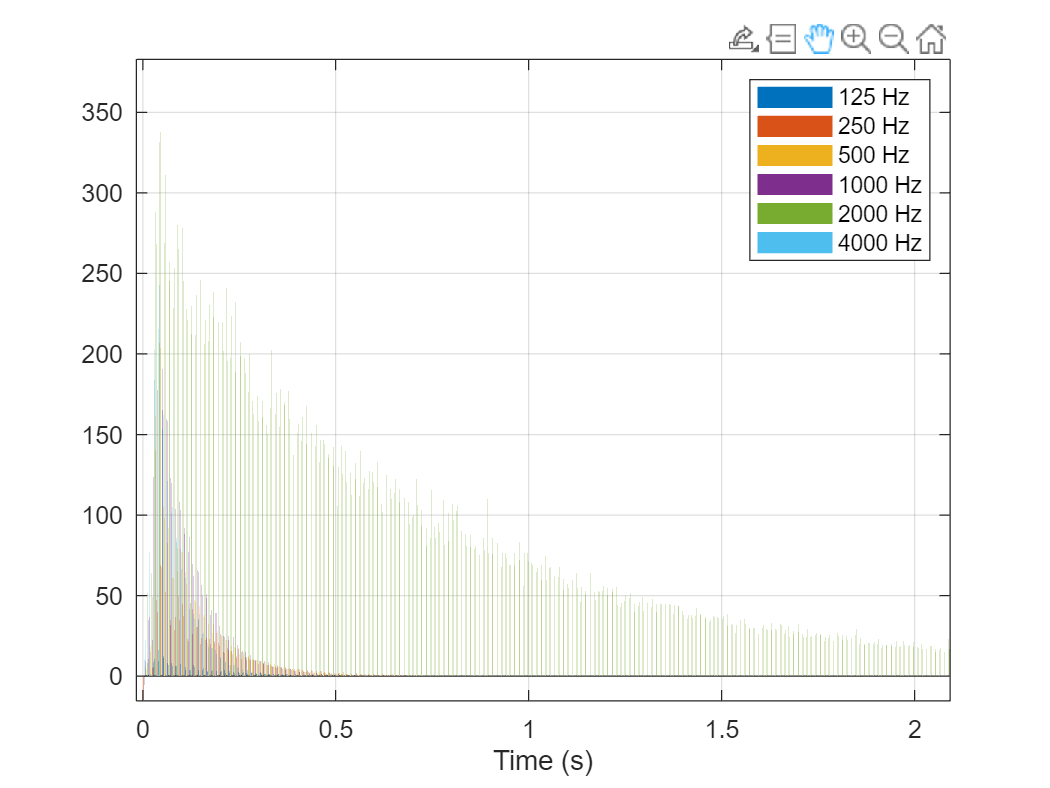

figure
bar(histTimeStep*(0:size(TFHist)-1),TFHist)
grid on
xlabel("Time (s)")
legend(["125 Hz","250 Hz","500 Hz","1000 Hz","2000 Hz","4000 Hz"])

## Generate Room Impulse Response

The energy histogram represents the envelope of the room impulse response. Synthesize the impulse response using a Poisson-distributed noise process [2]. 

### Generate Poisson Random Process

Define the audio sample rate (in Hz).

fs = 44100;

You model sound reflections as a Poisson random process. 

Define the start time of the process.

V = prod(roomDimensions);
t0 = ((2*V*log(2))/(4*pi*c^3))^(1/3); % eq 5.45 in [2]

Initialize the random process vector and the vector containing the times at which events occur.

poissonProcess = [];
timeValues = [];

Create the random process.

t = t0;
while (t<impResTime)
    timeValues = [timeValues t]; %#ok
    % Determine polarity.
    if (round(t*fs)-t*fs) < 0 
        poissonProcess = [poissonProcess 1]; %#ok
    else
        poissonProcess = [poissonProcess -1];%#ok
    end
    % Determine the mean event occurence (eq 5.44 in [2])
    mu = min(1e4,4*pi*c^3*t^2/V); 
    % Determine the interval size (eq. 5.44 in [2])
    deltaTA = (1/mu)*log(1/rand); % eq. 5.43 in [2])
    t = t+deltaTA;
end

Create a random process sampled at the specified sample rate.

randSeq = zeros(ceil(impResTime*fs),1);
for index=1:length(timeValues)
    randSeq(round(timeValues(index)*fs)) = poissonProcess(index);
end

### Pass Poisson Process Through Bandpass Filters

You create the impulse response by passing the Poisson process through bandpass filters centered at the frequencies in `FVect`, and then weighting the filtered signals with the received energy envelope computed in the histogram.

Define the lower and upper cutoff frequencies of the bandpass filters.

flow = [115 225 450 900 1800 3600];
fhigh = [135 275 550 1100 2200 4400];

Set the FFT length.

NFFT = 8192;

Create the short-time Fourier transform and inverse short-time Fourier transform objects you will use to filter the Poisson process and reconstruct it. Use a Hann window with 50% overlap.

win = hann(882,"symmetric");
sfft = dsp.STFT(Window = win,OverlapLength=441,FFTLength=NFFT,FrequencyRange="onesided");
isfft = dsp.ISTFT(Window=win,OverlapLength=441,FrequencyRange="onesided");
F = sfft.getFrequencyVector(fs);

Create the bandpass filters (use equation 5.46 in [2]).

RCF = zeros(length(FVect),length(F));
for index0 = 1:length(FVect)
    for index=1:length(F)
        f = F(index);
        if f<FVect(index0) && f>=flow(index0)
            RCF(index0,index) = .5*(1+cos(2*pi*f/FVect(index0)));
        end
        if f<fhigh(index0) && f>=FVect(index0)
            RCF(index0,index) = .5*(1-cos(2*pi*f/(FVect(index0)+1)));
        end
    end
end

Filter the Poisson sequence through the six bandpass filters.

frameLength = 441;
numFrames = length(randSeq)/frameLength;
y = zeros(length(randSeq),6);
for index=1:numFrames
    x = randSeq((index-1)*frameLength+1:index*frameLength);
    X = sfft(x);
    X = X.*RCF.';
    y((index-1)*frameLength+1:index*frameLength,:) = isfft(X);
end

### Combine the Filtered Sequences

Construct the impulse response by weighting the filtered random sequences sample-wise using the envelope (histogram) values.

Compute the times corresponding to the impulse response samples.

impTimes = (1/fs)*(0:size(y,1)-1);

Compute the times corresponding to the histogram bins.

hisTimes = histTimeStep/2 + histTimeStep*(0:nTBins);

Compute the weighting factors (equation 5.47 in [2]).

W = zeros(size(impTimes,2),numel(FVect));
BW = fhigh-flow;
for k=1:size(TFHist,1)
    gk0 = floor((k-1)*fs*histTimeStep)+1;
    gk1 = floor(k*fs*histTimeStep);
    yy = y(gk0:gk1,:).^2;
    val = sqrt(TFHist(k,:)./sum(yy,1)).*sqrt(BW/(fs/2));
    for iRay=gk0:gk1
        W(iRay,:)= val;
    end
end

Create the impulse response.

y = y.*W;
ip = sum(y,2);
ip = ip./max(abs(ip));

## Auralization

Plot the impulse response.

figure
plot((1/fs)*(0:numel(ip)-1),ip)

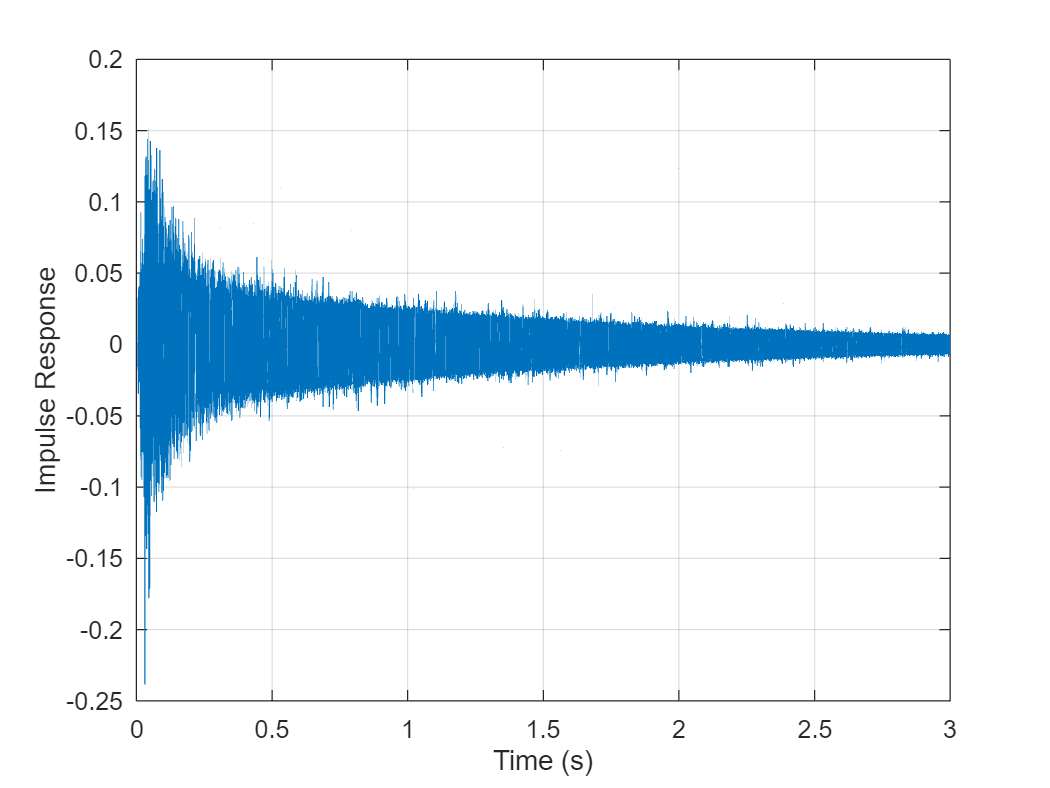

grid on
xlabel("Time (s)")
ylabel("Impulse Response")

Apply the impulse response to an audio signal.

[audioIn,fs] = audioread("FunkyDrums-44p1-stereo-25secs.mp3");
audioIn = audioIn(:,1);

Simulate the received audio by filtering with the impulse response.

audioOut = filter(ip,1,audioIn);
audioOut = audioOut/max(audioOut);

Listen to a few seconds of the original audio.

T = 10;
sound(audioIn(1:T*fs),fs)
pause(T)

Listen to a few seconds of the received audio.

sound(audioOut(1:T*fs),fs)

Error using sound
Audio data must be real and floating point.

## References

[1] "*Overview of geometrical room acoustic modeling techniques*", Lauri Savioja, Journal of the Acoustical Society of America 138, 708 (2015).

[2] "*Physically Based Real-Time Auralization of Interactive Virtual Environments*", Dirk Schröder, Aachen, Techn. Hochsch., Diss., 2011.

[3] "*Auralization: Fundamentals of Acoustics, Modelling, Simulation, Algorithms and Acoustic Virtual Reality*", Michael Vorlander, Second Edition, Springer. 

[4] [https://www.acoustic.ua/st/web_absorption_data_eng.pdf](https://www.acoustic.ua/st/web_absorption_data_eng.pdf)

[5] "*Scattering in Room Acoustics and Related Activities in ISO and AES*", Jens Holger Rindel, 17th ICA Conference, Rome, Italy, September 2001.

## Helper Functions

function plotRoom(roomDimensions,receiverCoord,sourceCoord,figHandle)
% PLOTROOM Helper function to plot 3D room with receiver/transmitter points
figure(figHandle)
X = [0;roomDimensions(1);roomDimensions(1);0;0];
Y = [0;0;roomDimensions(2);roomDimensions(2);0];
Z = [0;0;0;0;0];
figure;
hold on;
plot3(X,Y,Z,"k",LineWidth=1.5);   
plot3(X,Y,Z+roomDimensions(3),"k",LineWidth=1.5); 
set(gca,"View",[-28,35]); 
for k=1:length(X)-1
    plot3([X(k);X(k)],[Y(k);Y(k)],[0;roomDimensions(3)],"k",LineWidth=1.5);
end
grid on
xlabel("X (m)")
ylabel("Y (m)")
zlabel("Z (m)")
plot3(sourceCoord(1),sourceCoord(2),sourceCoord(3),"bx",LineWidth=2)
plot3(receiverCoord(1),receiverCoord(2),receiverCoord(3),"ro",LineWidth=2)
end

function X=RandSampleSphere(N)
% RANDSAMPLESPHERE Return random ray directions

% Sample the unfolded right cylinder
z = 2*rand(N,1)-1;
lon = 2*pi*rand(N,1);

% Convert z to latitude
z(z<-1) = -1;
z(z>1) = 1;
lat = acos(z);

% Convert spherical to rectangular co-ords
s = sin(lat);
x = cos(lon).*s;
y = sin(lon).*s;

X = [x y z];
end

function [surfaceofimpact,displacement] = getImpactWall(ray_xyz,ray_dxyz,roomDims)
% GETIMPACTWALL Determine which wall the ray encounters
surfaceofimpact = -1;
displacement = 1000;
%  Compute time to intersection with x-surfaces
if (ray_dxyz(1) < 0)
    displacement = -ray_xyz(1) / ray_dxyz(1);
    if displacement==0
        displacement=1000;
    end
    surfaceofimpact = 0;
elseif (ray_dxyz(1) > 0)
    displacement = (roomDims(1) - ray_xyz(1)) / ray_dxyz(1);
    if displacement==0
        displacement=1000;
    end
    surfaceofimpact = 1;
end
% Compute time to intersection with y-surfaces
if ray_dxyz(2)<0
    t = -ray_xyz(2) / ray_dxyz(2);
    if (t<displacement) && t>0
        surfaceofimpact = 2;
        displacement = t;
    end
elseif ray_dxyz(2)>0
    t = (roomDims(2) - ray_xyz(2)) / ray_dxyz(2);
    if (t<displacement) && t>0
        surfaceofimpact = 3;
        displacement = t;
    end
end
% Compute time to intersection with z-surfaces
if ray_dxyz(3)<0
    t = -ray_xyz(3) / ray_dxyz(3);
    if (t<displacement) && t>0
        surfaceofimpact = 4;
        displacement = t;
    end
elseif ray_dxyz(3)>0
    t = (roomDims(3) - ray_xyz(3)) / ray_dxyz(3);
    if (t<displacement) && t>0
        surfaceofimpact = 5;
        displacement = t;
    end
end
surfaceofimpact = surfaceofimpact + 1;

displacement = displacement * ray_dxyz;

end

function N = getWallNormalVector(surfaceofimpact)
% GETWALLNORMALVECTOR Get the normal vector of a surface
switch surfaceofimpact
    case 1
        N = [1 0 0];
    case 2
        N = [-1 0 0];
    case 3
        N = [0 1 0];
    case 4
        N = [0 -1 0];
    case 5
        N = [0 0 1];
    case 6
        N = [0 0 -1];
end

end

*Copyright 2021 The MathWorks, Inc.*